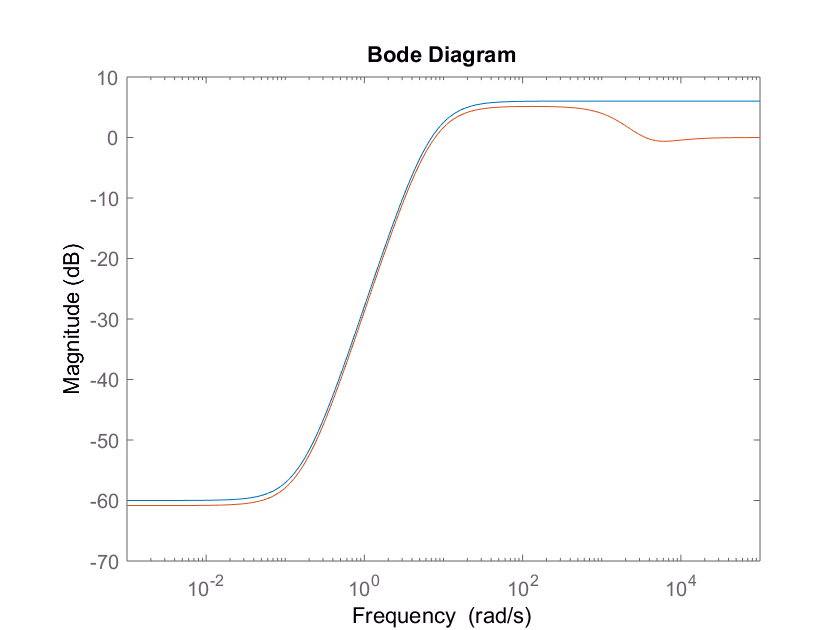

%Mixed sensitivty design for a flexible structure with a RHP zero
s = tf('s');  
G = (s-20)/(s^2+3.77*s+3948);
%Design goals
M = 2;  %Maximum sensitivity peak - not a bad general rule of thumb
A = 0.001;  %Low frequency attenuation
s = tf('s');
GAM = 0;  %Dummy value to start
BW = 1; %Trivial low value for bandwidth
Wp = 0;
K = 0;
while GAM<1
    Wp_old = Wp;
    Wp = (s/sqrt(M)+BW)^2/(s+BW*sqrt(A))^2;
    K_old = K;
    [K,CL,GAM,info] = mixsyn(G,Wp,1/10000,[]);
    BW = BW+1;
end
L_ms = G*K_old;
S_ms = 1/(1+L_ms);
T_ms = 1-S_ms;
figure
bodemag(1/Wp_old,S_ms)